# Inverted pendulum control with human in the loop

This livescript is a brief manual in support of the app ***invertedpendulum.mlapp***.   This is a simple interface to investigate two main learning outcomes.

- How do I control an inverted pendulum, balanced on a cart?

- What is the impact of a human in the loop on the efficacy of the control?   

More specifically the app allows the user to experiment with the following important aspects for control design.

- What is the impact of compensator gain on closed-loop performance?

- What is the impact of  lag in decision making/actuation and closed-loop performance?

- What is the impact of the delay on closed-loop performance?

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineering context

- Notional feedback design.

- Impact of varying gain K.

- Impact of lag (faulty or slow measurement and/or actuation).

- Impact of sample rate with discretisation.

- Impact of human in the loop.

- Image and components and animation.

## 1. Engineering context

Inverted pendulums have challenging dynamics which are representative of real systems such as  rockets and balancing systems in general and thus they are a nice simple example for students to practise control design and the impacts of real-life factors affecting performance.

A typical example has a pendulum placed on a cart which has lateral movement *p*. The pendulum is balanced by moving the cart. This resource focuses solely on the scenario where the intention is to maintain the pendulum in the upright position ($\left.\theta =0\right)$ and does not deal with the swing-up scenario which is altogether more challenging. The input *u* is a force, often applied through a belt drive to the cart; one could consider the input as being a voltage or similar to the motor driving the belt, but for this resource we wish to keep things simpler.

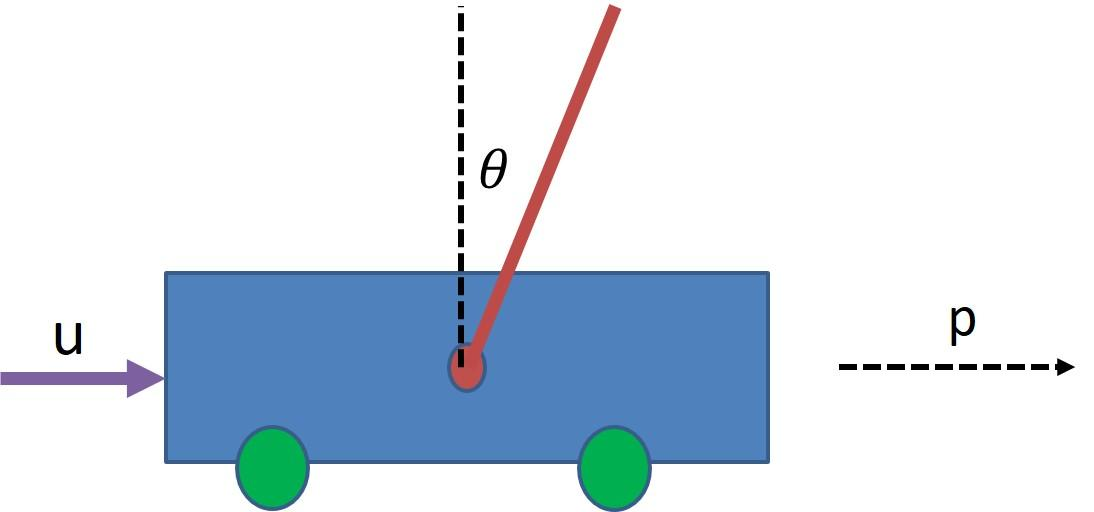

Simplified equations of motion can be represented as:


$$\left\lbrack \begin{array}{c}
\ddot{p} \\
\ddot{\theta} 
\end{array}\right\rbrack =$$

$$\left\lbrack \begin{array}{c}
\textrm{ku}\\
-b\dot{\theta} +g\;\sin \;\theta +u\;\cos \;\theta 
\end{array}\right\rbrack$$


Linearising about  $\theta =0$ gives the linearised model (valid for small angles):


$$\left\lbrack \begin{array}{c}
\ddot{p} \\
\ddot{\theta} 
\end{array}\right\rbrack =$$

$$\left\lbrack \begin{array}{c}
\textrm{ku}\\
-b\theta +g\theta +u
\end{array}\right\rbrack \;\;\Rightarrow X=\left\lbrack \begin{array}{c}
\dot{p} \\
\dot{\theta} \\
p\\
\theta 
\end{array}\right\rbrack \;\;\Rightarrow \;\;\dot{X} =\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & -b & 0 & g\\
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
k\\
1\\
0\\
0
\end{array}\right\rbrack u$$


For  this resource the output is taken as a single state, the angle $\theta$ and it is assumed that no other states are measured directly. Sensible values based on typical laboratory equipment are given by the following. 


$$-10\le u\le 10,\;-1\le p\le 1,\;b=0\ldotp 3,k=1,g=9\ldotp 8$$


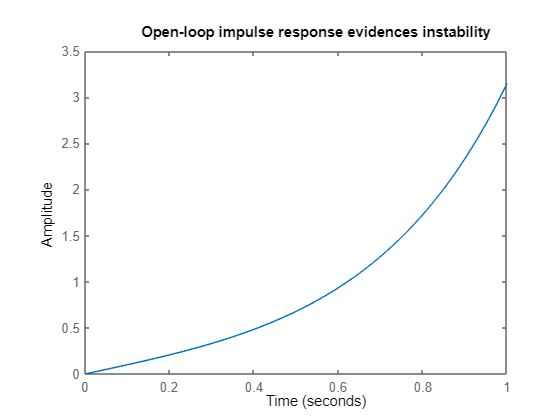

% Define the model with output theta
b=0.3; k=1; g=9.8;
A = [0 0 0 0; 0 -b 0 g;1 0 0 0;0 1 0 0];
B = [k;1;0;0];
C = [0 0 0 1];
D = 0;
G = ss(A,B,C,D);
impulse(G,1)
title('Open-loop impulse response evidences local instability')

## 2. Notional feedback design

The system is open-loop unstable around the upright position and thus aggresive control is needed to stabilise. This means that in terms of simple strategies we need to consider lead compensation or PD control. Here, to avoid issues with derivative kick, this resource will use lead compensation.

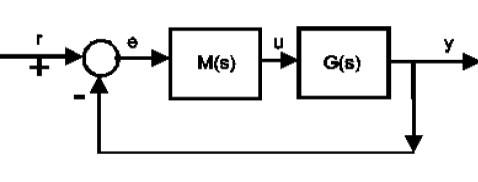

The open-loop poles are of the order of magnitude of 3, and thus, to have an impact the lead poles and zeros will need to be of similar magnitude. Hence, a simple lead could be something like:

$M=K\frac{s+3}{s+10}$   with ***K*** to be selected.

disp(' ')

disp('SECTION 2 BELOW')

SECTION 2 BELOW


Klead = 70*tf([1 3],[1 10])

Klead =
 
  70 s + 210
  ----------
    s + 10
 
Continuous-time transfer function.



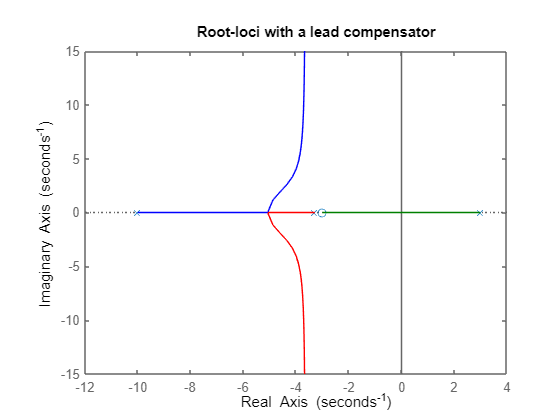

rlocus(G*Klead)
title('Root-loci with a lead compensator')

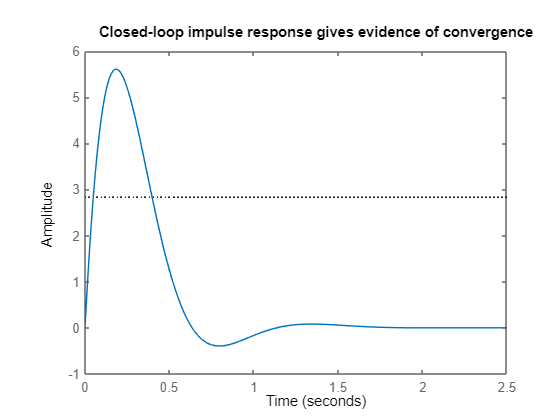

impulse(feedback(G*Klead,1));grid
title('Closed-loop impulse response gives evidence of convergence')

It is not the purpose of this resource to examine the compensator design in detail, so the focus will be on the choice of ***K*** and also the impact of: i) discretisation and ii) human operators.

## 3. Impact of varying the gain K

it is interesting to note that as the system is closed-loop unstable, making the compensator gain too small makes behaviour worse, even unstable, and not better. Similarly, too large values make the input too large (the notional limits on the input are 10) and unrealistic and also can cause more oscillation. Some simple illustrations are given here of how input and output behaviour varies for different ***K***, given a non-zero initial condition. 


disp('SECTION 3 BELOW')

X0 = [0;0;0;0.1;0];       % initial condition

SECTION 3 BELOW


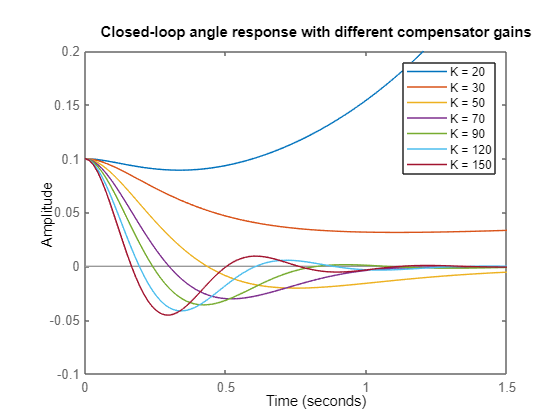

X0u = [0;0;0;0;0.1];       % initial condition
Klead = tf([1 3],[1 10]); % dynamic part of compensator
K=[20,30,50,70,90,120,150];         % gain part of compensator
time = linspace(0,1.5,101); % time instants for simulation
target = zeros(1,101);    % target - upright means theta = 0.
Gc = cell(1);

% Closed-loop responses
figure; clf
for k=1:length(K)
Gc{k} = feedback(G*Klead*K(k),1);
Gcu{k} = feedback(Klead*K(k),G);
lsim(Gc{k},target,time,X0); hold on
leg{k} = ['K = ',num2str(K(k))];
end
legend(leg)
ylim([-0.1 0.2])
title('Closed-loop angle response with different compensator gains')


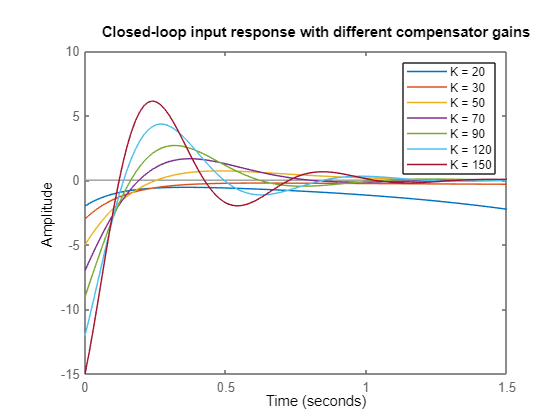

figure; clf
for k=1:length(K)
lsim(Gcu{k},target,time,X0u); hold on
end
legend(leg)
title('Closed-loop input response with different compensator gains')


## 4. Impact of lag (faulty or slow measurement and/or actuation)

It will be common place to have slow measurement and/or actuation due to limitations in the hardware. It is interesting to observe how behaviour degrades when such small delays are added and thus note the limitations of theory which assumes everything is perfect.

- A servo motor could have lag of the form (illustrative only): 

$\textrm{Lag}=0\ldotp 25\frac{s+2w}{s+0\ldotp 5w}$,

             so the force applied to the cart lags behind that requested by a small amount.

- A sensor could have lag associated to its own dynamics; ideally this would be at a very fast time scale but problems could occur if it is not.

Both these effects can be investigated at a conceptual level by adding a simple lag component with a variable ***w*** (frequency of maximum phase rotation) to the compensator and comparing behaviour with and without lag. Users can experiment with the impact of the value ***w ***on the closed-loop behaviour***.***

Below a default lead compensator uses the insight from section 3 and is given as: $M=70\frac{s+3}{s+10}$

**CORE OBSERVATION**: Adding the lag component means that the motor is slower to act and thus less able to control the dynamics. The consequence is greater oscillation and larger movements overall of both the motor and the pendulum.


disp('SECTION 4 BELOW')

X0 = [0;0;0;0.1;0];       % initial condition

SECTION 4 BELOW


X02 = [0;0;0;0.1;0;0];       % initial condition
Klead = 70*tf([1 3],[1 10]); % lead compensator
w=[5,10,20,30,50];         % frequency part of lag
time = linspace(0,1.5,101); % time instants for simulation
target = zeros(1,101);    % target - upright means theta = 0.
Gc1 = cell(1); leg=cell(1);

% Closed-loop responses
figure; clf
Gc = feedback(G*Klead,1);
lsim(Gc,target,time,X0); hold on
leg{1}='No lag';
for k=1:length(w)
Ktotal = Klead*tf(0.25*[1,2*w(k)],[1,0.5*w(k)]);
Gc1{k} = feedback(G*Ktotal,1);
lsim(Gc1{k},target,time,X02);
leg{k+1} = ['w = ',num2str(w(k))];
end
legend(leg)
title('Closed-loop angle response with different lag corner frequencies')

## 5. Impact of sample rate with discretisation (not included in the app)

In practice compensation is often implemented discretely due to the use of computing. It is interesting to investigate he impact of the chosen sample rate of the efficacy of the compensator and thus to discern, limits on the required sample rate to ensure effective closed-loop behaviour.

A default lead compensator uses the insight from section 3 and is given as: $M=70\frac{s+3}{s+10}$

The code here produces plots of the output at different sample rates and overlays with the expected performance for continuous time control. 

**NOTE**: Not covered here, but users may like to combine this with the previous section and consider the impact of having both discretation and measurement/actuation lag.

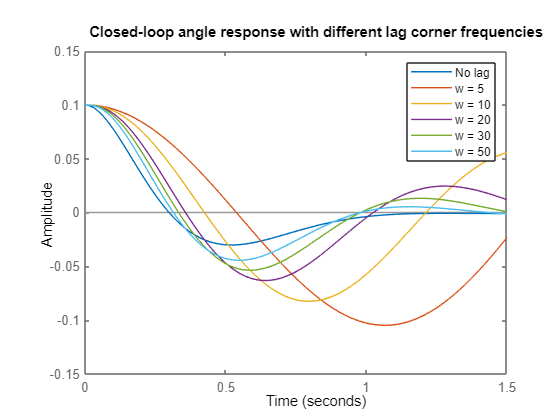

disp('SECTION 5 BELOW')

X0 = [0;0;0;0.1;0];       % initial condition
Klead = 70*tf([1 3],[1 10]); % lead compensator
sampletime = [0.01,0.025,0.05,0.1,0.15];         % sampling time
time = linspace(0,1.5,101); % time instants for simulation
target = zeros(1,101);    % target - upright means theta = 0.
Gc1 = cell(1); leg=cell(1);


SECTION 5 BELOW


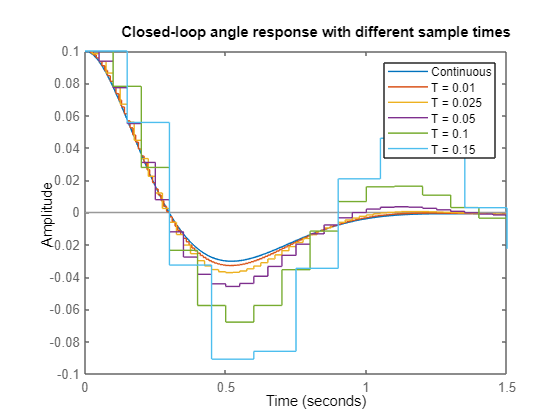

% Closed-loop responses
figure; clf
Gc = feedback(G*Klead,1);
lsim(Gc,target,time,X0); hold on
leg{1}='Continuous';
for k=1:length(sampletime);
    Gd = c2d(G,sampletime(k));
    Kleadd = c2d(Klead,sampletime(k),'tustin');

    Gc1{k} = feedback(Gd*Kleadd,1);
    time = 0:sampletime(k):1.5;
    lsim(Gc1{k},zeros(1,length(time)),time,X0);
    leg{k+1} = ['T = ',num2str(sampletime(k))];
end
legend(leg)
title('Closed-loop angle response with different sample times')

## 6. Impact of human in the loop 

Users can use the app to investigate the issues discussed in this section.

Humans are generally much slower than computers at both monitoring, decision making and implementing decisions. Consequently, one could form a model of human behaviour as a combination of delay and lag, for example:


$$\textrm{Human}=Ke^{-\textrm{sT}} \frac{s+\textrm{wr}}{s+w};r>1$$


The delay can vary from about 0.1 sec (response rates of sprinters to the gun at the start of a race), to longer where more considered decision making is required. The lag component linked to human action (move a hand, finger, arm, etc.) will also vary depending on what operation is required; short finger movements can be very quick (say $\left.w=2\right)$ but bigger movements of the limbs can be slower.

The user might like to investigate for themselves, using code similar to the above, what impact replacing the DC servo dynamics and computer with a human would have on control of the inverted pendulum. A simple human model for this scenario could be something like:

$\textrm{Human}=0\ldotp 25e^{-0\ldotp 1} \frac{s+40}{s+10}$;                  

The human effects are added to the lead compensator, so the overall compensator would be something like:

 
$$M=\left(70\frac{s+3}{s+10}\right)\times \left(0\ldotp 25e^{-0\ldotp 1s} \frac{s+40}{s+10}\right)$$


Indeed one could also add additional lag associated to the hardware, if desired, as discussed in section 4.

**REMARK**: The app uses a Pade approximant for delay as the feedback tools do not work well with delay and non-zero initial conditions.

**REMARK 2**: User will note that as this system is hard to stabilise in general terms, it is necessary for delay to be small, say less than 0.1, and for the time constant of the human reaction to be of the order of a tenth of second. Inclusion of the human leads to slower motor movements which are unable to counter the systme dynamics fast enough, leading to poorer behaviour overall. The  lead compensator demands more active motor signals, but these cannot be delivered.

## 7. Image and components and animation

The image shows a cart with a pendulum and a belt for moving the cart. The belt is driven by a DC servo or hand represented by the rotating disc/hand.

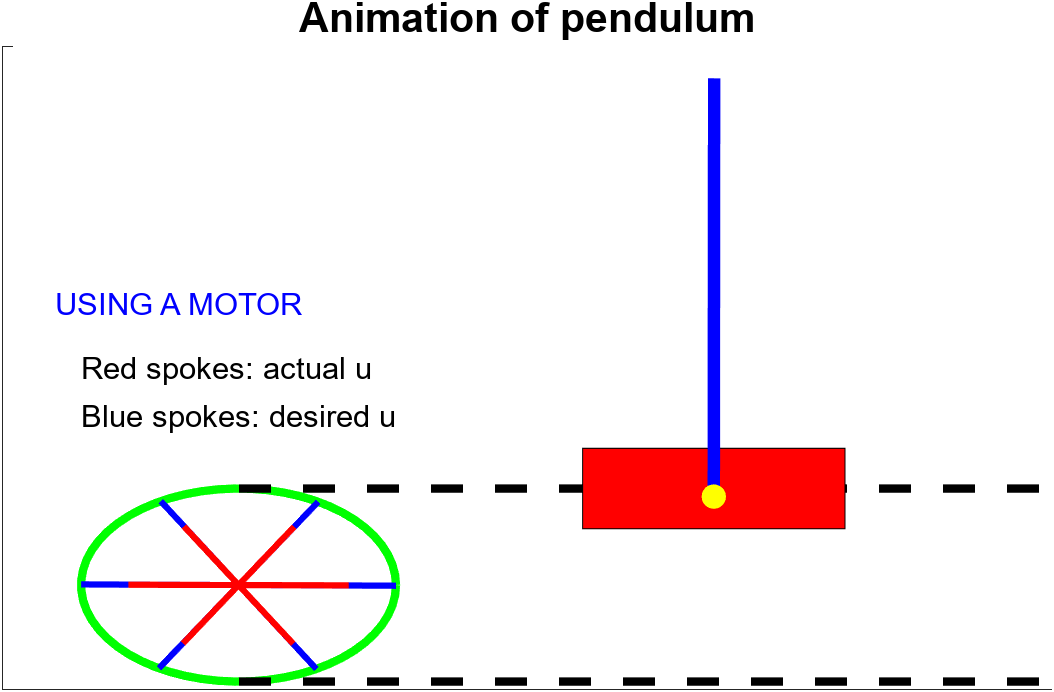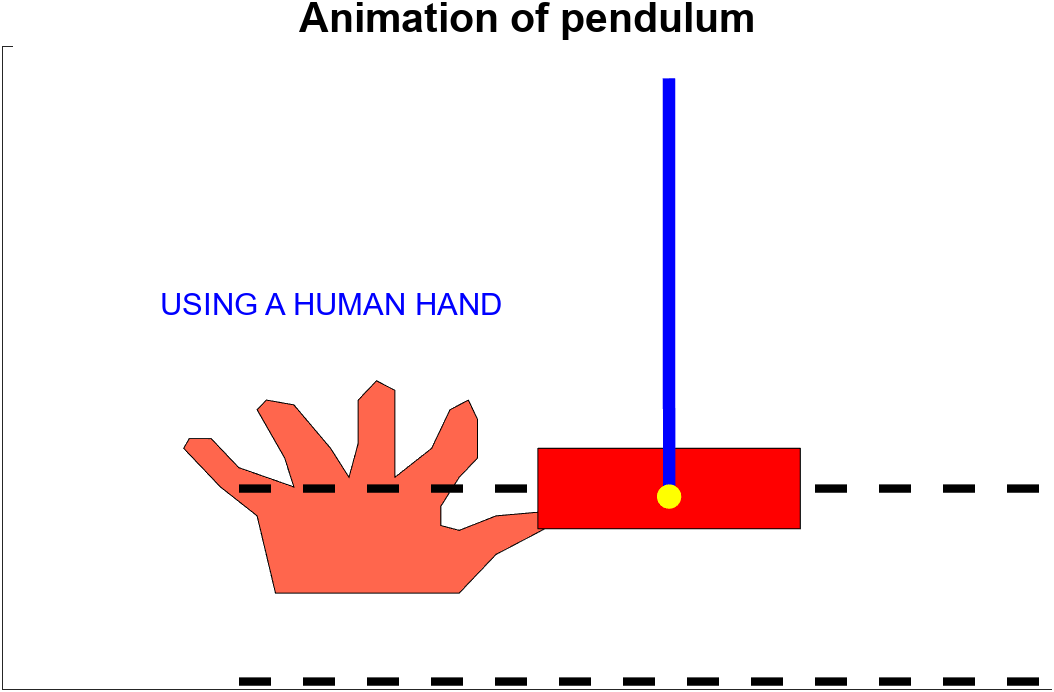

- Lag is represented by a 2nd rotating disc. The inner disc spins at the desired 'speed' whereas the outer disc spins at the delivered speed.

- Replacing the motor by a human has the motor replaced by a belt. Again, the difference between the actual hand movement and desired hand movement is animated so users can see the impact of the lag.

The user can change only a few parameters in order to keep the app simple and transparent. 

- The gain parameter within the lead compensator (orange box).

- The frequency *w*  asscociated to the lag component of the servo.

- The delay introduced by a human operator.

- The lag frequency* v*  associated to human decision marking.

- When the human operator is selected on, the motor lag is not included.

The app keeps track of previous choices so that overlaying of responses can be used to inv3estigate the impact of parameter changes.  Use the refresh button to begin again.

The cart parameters are not changed as this offers little further useful insight.

The simulation assumes a non-zero initial condition and requires the control law to return the pendulum to the upright position.